# HW13: Sections 6.1 1-4 & 6.3 1-2

# Amelia Rotondo 

# CWID: 887925113

## Section 6.1 

#### 6.1.1:

% Define the transition matrix
P = [0.25, 0.75;  % Grease Dining Hall
     0.07, 0.93]; % Sweets Dining Hall
% x = [G, S]

% Solve xP = x:
    % xP - x = 0
    % x(P - I) = 0
    % (P'-I)x = 0

% Since the rows of P add up to 1, 
    % x*(1) = 1
    % (1')x = 1

% Therefore, (P'-I)x = 0, and (1')x = 1 

% A is a vector of [(P-I); 1] , b is [0; 1]
A = P' - eye(2);
A(2, :) = 1;
b = [0; 1];

% Solve the system of equations
x = A \ b;

% Display the results
fprintf('Long-term percentage of Grease Dining Hall: %.2f%%\n', x(1)*100);

Long-term percentage of Grease Dining Hall: 8.54%


fprintf('Long-term percentage of Sweet Dining Hall : %.2f%%\n', x(2)*100);

Long-term percentage of Sweet Dining Hall : 91.46%


#### 6.1.2:

% Define the transition matrix
P = [0.25, 0.25, 0.50;   % Grease Dining Hall
     0.10, 0.30, 0.60;   % Sweet Dining Hall
     0.05, 0.15, 0.80];  % Pizza delivery
% x = [G, S, P]

% Solve xP = x:
    % xP - x = 0
    % x(P - I) = 0
    % (P'-I)x = 0

% Since the rows of P add up to 1, 
    % x*(1) = 1
    % (1')x = 1

% Therefore, (P'-I)x = 0, and (1')x = 1 

% A is a matrix of [(P-I); 1] , b is [0; 0; 1]
A = P' - eye(3);
A(3, :) = 1;
b = [0; 0; 1];

% Solve the system of equations
x = A \ b;

% Display the results
fprintf('Long-term percentage at Grease Dining Hall: %.2f%%\n', x(1)*100);

Long-term percentage at Grease Dining Hall: 7.41%


fprintf('Long-term percentage at Sweet Dining Hall : %.2f%%\n', x(2)*100);

Long-term percentage at Sweet Dining Hall : 18.52%


fprintf('Long-term percentage using Pizza Delivery : %.2f%%\n', x(3)*100);

Long-term percentage using Pizza Delivery : 74.07%


#### 6.1.3:

Equilibrium State Solution:

% Define the transition matrix
P = [0.6, 0.4;  % Orlando
     0.3, 0.7]; % Tampa

% Set up the system of equations
A = P' - eye(2);
A(2, :) = 1;
b = [0; 1];

% Solve the system of equations
x = A \ b;

% Display the equilibrium distribution
fprintf('Equilibrium Distribution of Cars: \nOrlando: %.2f\nTampa  : %.2f\n', x(1), x(2));

Equilibrium Distribution of Cars: 
Orlando: 0.43
Tampa  : 0.57


Different Starting State Simulations:

% Define different starting states
start_states = [1, 0; 0.5, 0.5; 0.2, 0.8; 0, 1];

% Number of iterations for the simulation
iterations = 100;

% Simulate the Markov chain for each starting state
for i = 1:size(start_states, 1)
    state = start_states(i, :);
    fprintf('Starting states: Orlando: %.2f, Tampa: %.2f', state(1), state(2));
    
    for iter = 1:iterations
        state = state * P;
    end
    
    fprintf('    Final State: Orlando: %.2f, Tampa: %.2f\n', state(1), state(2));
    fprintf('---------------------------------------\n')
end

Starting states: Orlando: 1.00, Tampa: 0.00

    Final State: Orlando: 0.43, Tampa: 0.57


---------------------------------------


Starting states: Orlando: 0.50, Tampa: 0.50

    Final State: Orlando: 0.43, Tampa: 0.57


---------------------------------------


Starting states: Orlando: 0.20, Tampa: 0.80

    Final State: Orlando: 0.43, Tampa: 0.57


---------------------------------------


Starting states: Orlando: 0.00, Tampa: 1.00

    Final State: Orlando: 0.43, Tampa: 0.57


---------------------------------------


#### 6.1.4:

Equilibrium State Solution:

% Define the transition matrix for voters
P = [0.75, 0.05, 0.20;  % Republicans
     0.20, 0.60, 0.20;  % Democrats
     0.40, 0.20, 0.40]; % Independents

% Set up the system of equations
A = P' - eye(3);
A(3, :) = 1;
b = [0; 0; 1];

% Solve the system of equations
x = A \ b;

% Display the equilibrium distribution
fprintf('Equilibrium Distribution of Voters: \nRepublicans  : %.2f\nDemocrats   : %.2f\nIndependents: %.2f\n', x(1), x(2), x(3));

Equilibrium Distribution of Voters: 
Republicans  : 0.56
Democrats   : 0.19
Independents: 0.25


Different Starting State Simulations:

% Define different starting states for voters
start_states = [1/3, 1/3, 1/3; 0.9, 0.05, 0.05; 0.1, 0.1, 0.8; 0, 0, 1];

% Number of iterations for the simulation
iterations = 100;

% Simulate the Markov chain for each starting state
for i = 1:size(start_states, 1)
    state = start_states(i, :);
    fprintf('\nStarting States: Republicans: %.2f, Democrats: %.2f, Independents: %.2f\n', state(1), state(2), state(3));
    
    for iter = 1:iterations
        state = state * P;
    end
    
    fprintf('    Final State: Republicans: %.2f, Democrats: %.2f, Independents: %.2f\n', state(1), state(2), state(3));
    fprintf('---------------------------------------\n');
end


Starting States: Republicans: 0.33, Democrats: 0.33, Independents: 0.33


    Final State: Republicans: 0.56, Democrats: 0.19, Independents: 0.25


---------------------------------------



Starting States: Republicans: 0.90, Democrats: 0.05, Independents: 0.05


    Final State: Republicans: 0.56, Democrats: 0.19, Independents: 0.25


---------------------------------------



Starting States: Republicans: 0.10, Democrats: 0.10, Independents: 0.80


    Final State: Republicans: 0.56, Democrats: 0.19, Independents: 0.25


---------------------------------------



Starting States: Republicans: 0.00, Democrats: 0.00, Independents: 1.00


    Final State: Republicans: 0.56, Democrats: 0.19, Independents: 0.25


---------------------------------------


## Section 6.3

#### 6.3.1:

Predicting Weight as a function of Height using `fitlm(x, y)`

% Data
x = [60:70, 71:80]';
y = [132, 136, 141, 145, 150, 155, 160, 165, 170, 175, 180, 185, 190, 195, 201, 206, 212, 218, 223, 229, 234]';

% Fit a linear regression model
mdl = fitlm(x, y);

% Display the model
disp(mdl)

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -178.5       2.8831    -61.911    2.1977e-23
    x1              5.1364     0.041034     125.17    3.5284e-29


Number of observations: 21, Error degrees of freedom: 19
Root Mean Squared Error: 1.14
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 1.57e+04, p-value = 3.53e-29


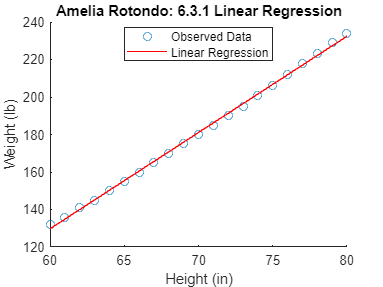


% Use the model to predict weight for a given height
yy = predict(mdl, x);

% Calculate residuals
residuals = y - yy;

% Plot the data and the regression line
figure(1); clf; hold on;
scatter(x, y, 'o'); % observed data
plot(x, yy, '-r'); % regression line
xlabel('Height (in)');
ylabel('Weight (lb)');
legend('Observed Data', 'Linear Regression', 'Location', 'best');
title('Amelia Rotondo: 6.3.1 Linear Regression');
hold off;

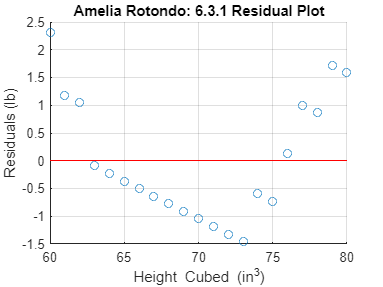


% Plot the residuals
figure(2); clf; hold on;
scatter(x, residuals, 'o');
xlabel('Height Cubed (in^3)');
ylabel('Residuals (lb)');
title('Amelia Rotondo: 6.3.1 Residual Plot');
hline = refline([0 0]);
hline.Color = 'r';
grid on;
hold off;

#### 6.3.2:

% Data
x = [60:70, 71:80]';
y = [132, 136, 141, 145, 150, 155, 160, 165, 170, 175, 180, 185, 190, 195, 201, 206, 212, 218, 223, 229, 234]';

% Transform height to the cube of the height
x_cubed = x.^3;

% Fit a linear regression model
mdl_cubed = fitlm(x_cubed, y);

% Display the model
disp(mdl_cubed)

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)       59.458        1.2759    46.602    4.6899e-21
    x1             0.0003467    3.5247e-06    98.364    3.4153e-27


Number of observations: 21, Error degrees of freedom: 19
Root Mean Squared Error: 1.45
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 9.68e+03, p-value = 3.42e-27


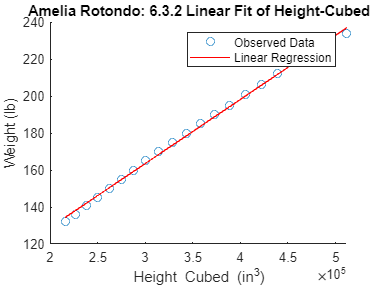


% Use the model to predict weight for a given height
yy_cubed = predict(mdl_cubed, x_cubed);

% Calculate residuals
residuals_cubed = y - yy_cubed;

% Plot the regression results
figure(3); clf; hold on;
scatter(x_cubed, y, 'o'); % observed data
plot(x_cubed, yy_cubed, '-r'); % regression line
xlabel('Height Cubed (in^3)');
ylabel('Weight (lb)');
legend('Observed Data', 'Linear Regression');
title('Amelia Rotondo: 6.3.2 Linear Fit of Height-Cubed');
hold off;

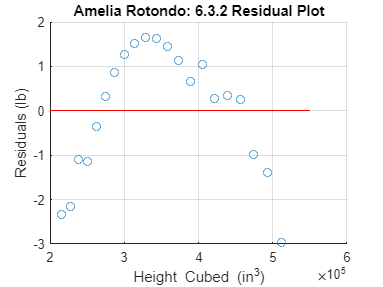


% Plot the residuals
figure(4); clf; hold on;
scatter(x_cubed, residuals_cubed, 'o');
xlabel('Height Cubed (in^3)');
ylabel('Residuals (lb)');
title('Amelia Rotondo: 6.3.2 Residual Plot');
hline = refline([0 0]);
hline.Color = 'r';
grid on;
hold off;